Specific Tasks for this Robotics 41013 Assignment

1) Build a D&H model of two UR3s. Build simulated graphical models of the chosen robots, the parts to be assembled and the surrounding environment using Matlab and the Matlab robotics toolbox. **Ensure the mounting location of the robot base can be easily modified.**

% 0) SETUP and creating robots
clear all; close all;

set(0,'DefaultFigureWindowStyle','docked');

arm1 = UR3({'',''},'arm1');

robot_name =arm1
Logging on file: log/log_UR3_arm1.log


arm2 = UR3({'',''},'arm2');

robot_name =arm2
Logging on file: log/log_UR3_arm2.log


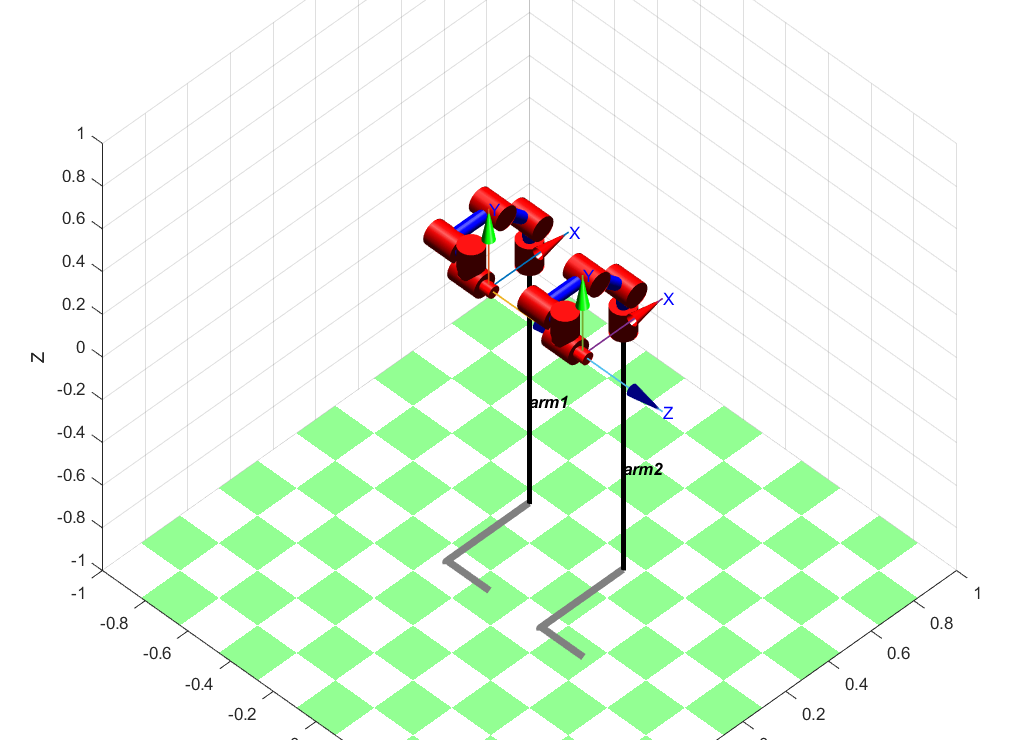


arm1.SetBase( transl(-0.22,0.22,0.18) * trotx(deg2rad(0)) * troty(deg2rad(0)) * trotz(deg2rad(0)) );
arm2.SetBase( transl(0.22,0.22,0.18) * trotx(deg2rad(0)) * troty(deg2rad(0)) * trotz(deg2rad(0)) );

figure(1);
%q0 = [0 0 0 0 0 0];
q0 = deg2rad([90 -45 45 0 0 0]);
arm1.model.plot(q0);
hold on;
arm2.model.plot(q0);
view(45,45);


%arm1.PlotAndColourRobot();
%hold on;
%arm2.PlotAndColourRobot();
%arm1.PlotAndColourWorld();

% 0.1) TEST: Testing if the model is OK
test = false;
if test == true
    q0 = [0 0 0 0 0 0];
    %arm1.model.plot3d(q0);
    
    %arm1.PlotWithColor(q0);
    %campos([2.9759   12.5788    8.1104]);
    %camzoom(1.7)
    
    load('ur3_q.mat');
    for i=1:size(q,1)
        if (mod(i,28) == 0) % aprox. the same time as the video
            arm1.model.plot(q(i,:));
            hold on;
            arm2.model.plot(q(i,:));
        end
    end
end


2) On the submission day you will be given a specific mounting transform for each robot base, and for the demonstration you will need to be able to rapidly determine and demonstrate to your assessors/peers:

a) the maximum reach of each arm (radius from top and side view);

b) the approximate volume in m3 that the entire arm may exist in (hint: consider the positions of each joint for a large, representative sample of joint positions) and;

% 1) VOLUME: plotting
%figure(2);

%h1_ = arm1.PlotVolume(1, arm2.model.base, 'red'); % argument (1) indicates that we need to create a new pointCloud to plot the volume
%drawnow();
%hold on;
%h2_ = arm2.PlotVolume(1, arm1.model.base, 'blue');
%drawnow();

%pause(20);
%delete(h1_);
%delete(h2_);

c) the updated location of proposed safety infrastructure given that mounting position.

% 1.1) VOLUME: calculating
%a = (max(arm1.pointCloud(:,1)) - min(arm1.pointCloud(:,1)))/2;
%%b = (max(arm1.pointCloud(:,2)) - min(arm1.pointCloud(:,2)))/2;
%c = (max(arm1.pointCloud(:,3)) - min(arm1.pointCloud(:,3)))/2;

%volume = (4/3)*pi*a*b*c;
%disp(strcat("Approximate volume (m^3) = ",num2str(volume)));

3) The three parts must be put together as shown in Fig 1, i.e. housing top / bottom and the circuit board. The actual transform of the three parts will be given on the day of submission (for testing purposes you should set the locations to be random within some bounds). Assume that once the robot end-effector moves to the given part location it automatically and successfully grasps the part. You will need to demonstrate the following steps in the assembly:

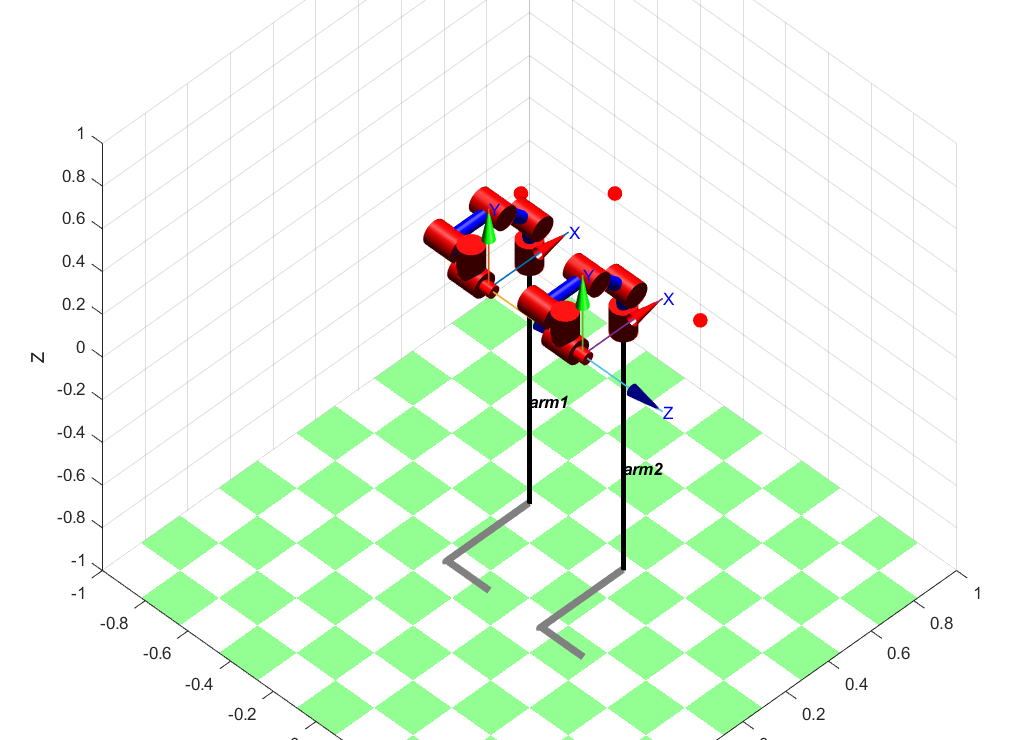

% go back to original position
figure(1);
q0 = deg2rad([90 -45 45 0 0 0]);
arm1.model.plot(q0);
hold on;
arm2.model.plot(q0);

arm1CurrentQ = arm1.model.getpos();
arm2CurrentQ = arm2.model.getpos();

% 2) SETTING UP OBJECTS POSES
topHousingPose   = transl(0.42,0.38,0.2) * trotx(deg2rad(180)) * troty(deg2rad(0)) * trotz(deg2rad(0));
botHousingPose   = transl(-0.42,0.38,0.2) * trotx(deg2rad(180)) * troty(deg2rad(0)) * trotz(deg2rad(0));
circuitBoardPose = transl(-0.20  , 0.6    ,0.2) * trotx(deg2rad(180)) * troty(deg2rad(0)) * trotz(deg2rad(0));

figure(1); hold on;
aux = transl(topHousingPose); x = aux(1); y = aux(2); z = aux(3);
plot3(x, y, z,'r.', 'MarkerSize',30); % magenta dot where we should place it
aux = transl(botHousingPose); x = aux(1); y = aux(2); z = aux(3);
plot3(x, y, z,'r.', 'MarkerSize',30); % magenta dot where we should place it
aux = transl(circuitBoardPose); x = aux(1); y = aux(2); z = aux(3);
plot3(x, y, z,'r.', 'MarkerSize',30); % magenta dot where we should place it

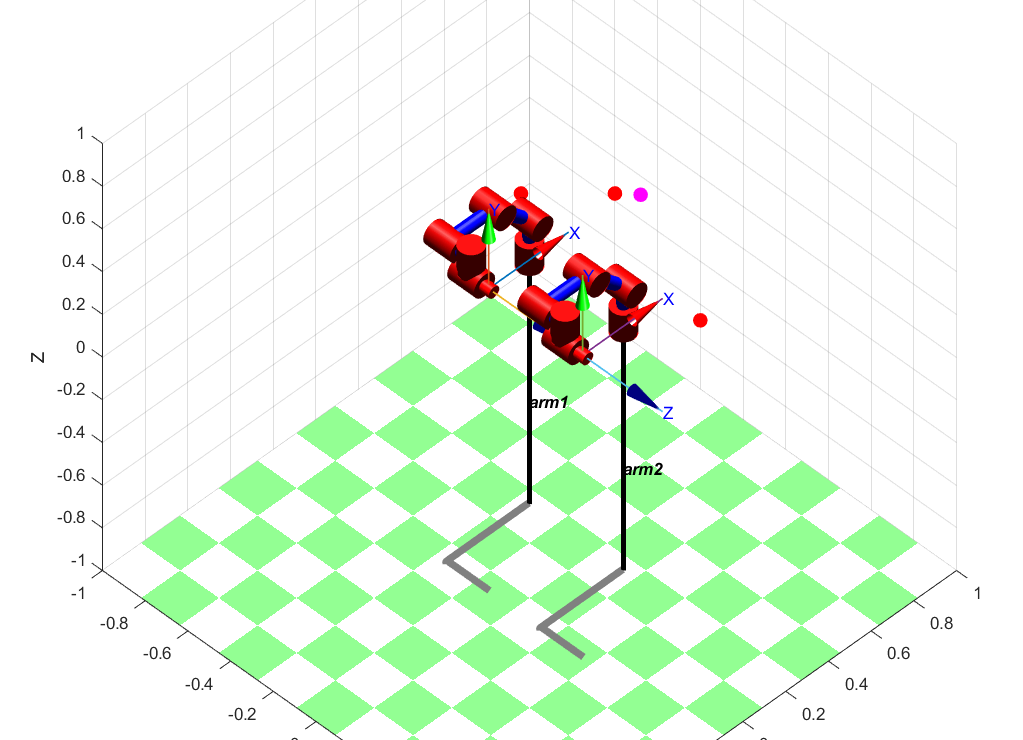

% ASSEMBLY POSES
arm1AssemblyPose = transl(0.0597, 0.4607, 0.4762)*trotx(0)*troty(0)*trotz(pi); % rotate pi around Z
arm2AssemblyPose = transl(0.0597, 0.4607, 0.5762)*trotx(pi)*troty(0)*trotz(0); % rotate pi around X to put Z down


%arm1AssemblyQ = arm1.model.ikcon(arm1AssemblyPose, arm1CurrentQ);
arm1AssemblyQ = arm1.model.ikcon(arm1AssemblyPose, [-1.3823   -2.0191    2.3051   -2.3908    1.5710   -0.4420]);
%arm2AssemblyQ = arm2.model.ikcon(arm2AssemblyPose, arm2CurrentQ);
arm2AssemblyQ = arm2.model.ikcon(arm2AssemblyPose, [-2.6771   -1.7123    0.8005   -1.1127   -1.5708   -1.1697]);


aux = transl(arm1AssemblyPose); x = aux(1); y = aux(2); z = aux(3);
figure(1); hold on;
plot3(x, y, z,'m.', 'MarkerSize',30); % magenta dot where we should place it

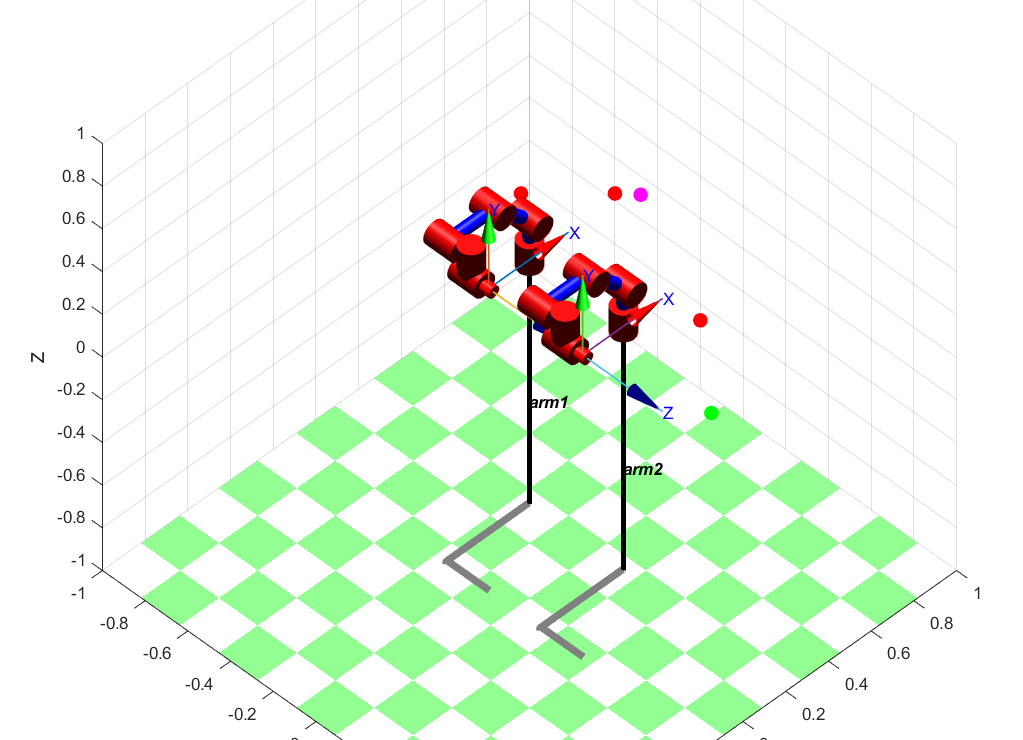

% RELEASE POSE
releasePose = transl(0.7317, 0.1197, 0.1706)*trotx(3.1352)*troty(-0.2654)*trotz(0.1403);
aux = transl(releasePose); x = aux(1); y = aux(2); z = aux(3);
figure(1); hold on;
plot3(x, y, z,'g.', 'MarkerSize',30); % green dot where we should place it

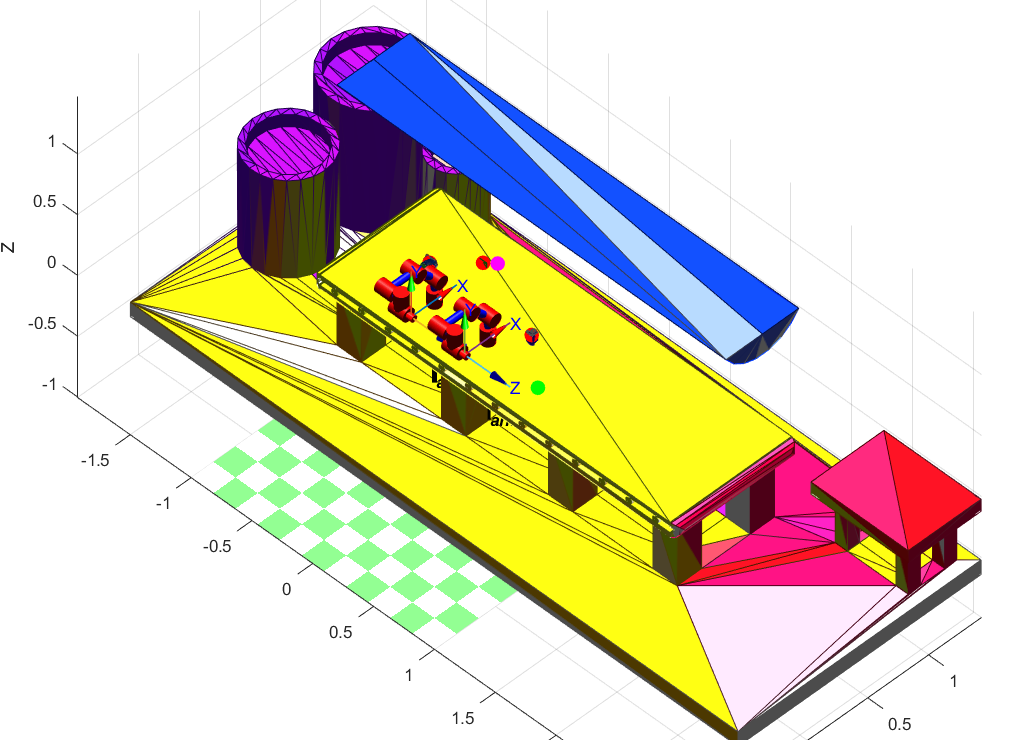

arm1.PlotWorld();
hold on;
axis equal;
% ID
% Top, PCB, Bottom -> 1, 2, 3
figure(1);
[top_h  , topVerts, topVertexCount , top_points ] = arm1.PlotParts(1,topHousingPose);
[circ_h ,circVerts, circVertexCount, circ_points] = arm1.PlotParts(2,circuitBoardPose);
[bot_h  , botVerts, botVertexCount , bot_points ] = arm1.PlotParts(3,botHousingPose);


%arm1.PlotAndColourRobot();
%hold on;
%arm2.PlotAndColourRobot();

a) Determine a pose that can pick up each of the parts;

**R: Given an initial pose for the 2 manipulators and for the 3 parts, we must be able to grasp, at first, one object with each manipulator. So arm1 grabs obj1 and arm2 grabs obj2. Make the arm closest to the bottom shell grasp the circuit board (because of task 3-d )**

Identify which part is closer to which arm

Considering all parts are within reach of both arms

% 3) SELECTING arms for each part
util = Utilities();
% NOTE THAT: since we already plotted the robots with names 'arm1' and 'arm2', since we are changing them now
% we can issue a command like arm1.model.plot() and see arm2 moving on the drawing, but thats not a real issue
% just a plotting bug
if util.CloserArm(topHousingPose, arm1.model, arm2.model) == 2 % we're making sure arm1 always grasps topHousing
    aux = arm1; arm1 = arm2; arm2 = aux; 
    % we need to change AssemblyQ as well
    arm1AssemblyPose = transl(0.0597, 0.4607, 0.4762)*trotx(0)*troty(0)*trotz(pi); % rotate pi around Z
    arm2AssemblyPose = transl(0.0597, 0.4607, 0.5762)*trotx(pi)*troty(0)*trotz(0); % rotate pi around X to put Z down
    
    
    %arm1AssemblyQ = arm1.model.ikcon(arm1AssemblyPose, arm1CurrentQ);
    arm1AssemblyQ = arm1.model.ikcon(arm1AssemblyPose, [-1.3823   -2.0191    2.3051   -2.3908    1.5710   -0.4420]);
    %arm2AssemblyQ = arm2.model.ikcon(arm2AssemblyPose, arm2CurrentQ);
    arm2AssemblyQ = arm2.model.ikcon(arm2AssemblyPose, [-2.6771   -1.7123    0.8005   -1.1127   -1.5708   -1.1697]);
end

disp("Arm 1 is getting topHousing and Arm 2 is getting circuitBoard then botHousing");

Arm 1 is getting topHousing and Arm 2 is getting circuitBoard then botHousing



% 2.1) UPDATING robots joint states
arm1CurrentQ    = arm1.model.getpos(); % to make it easier to find joint positions later
arm2CurrentQ    = arm2.model.getpos(); % to make it easier to find joint positions later
 
arm1GoalPose = topHousingPose;
arm2GoalPose = circuitBoardPose;

arm1_elbowUp = deg2rad([90 -45 90 0 0 0]);
arm1_elbowDown = [1.5708   -2.9880   -2.1851   -1.4557         0         0];

arm2_elbowUp = deg2rad([90 -45 90 0 0 0]);
arm2_elbowDown = [-1.0018   -0.7226    1.5684   -1.3823   -1.5708   -0.6903];

%arm1GoalQ    = wrapToPi(arm1.model.ikine(arm1GoalPose, arm1_elbowUp));
%arm2GoalQ    = wrapToPi(arm2.model.ikine(arm2GoalPose, arm2_elbowUp));

arm1GoalQ    = wrapToPi(arm1.model.ikcon(arm1GoalPose, arm1_elbowDown));
arm2GoalQ    = wrapToPi(arm2.model.ikcon(arm2GoalPose, arm2_elbowDown));


b) Simulate the robot movement in a smooth joint-position controlled motion between the starting pose and the first two pickup tasks: pick up the top of the housing, and circuit board;

**R: Given poses A1, B1, for the first task (arm1 grabs obj1), and A2, B2 (arm2 grabs obj2), we must interpolate joint positions in order to go from A to B.**

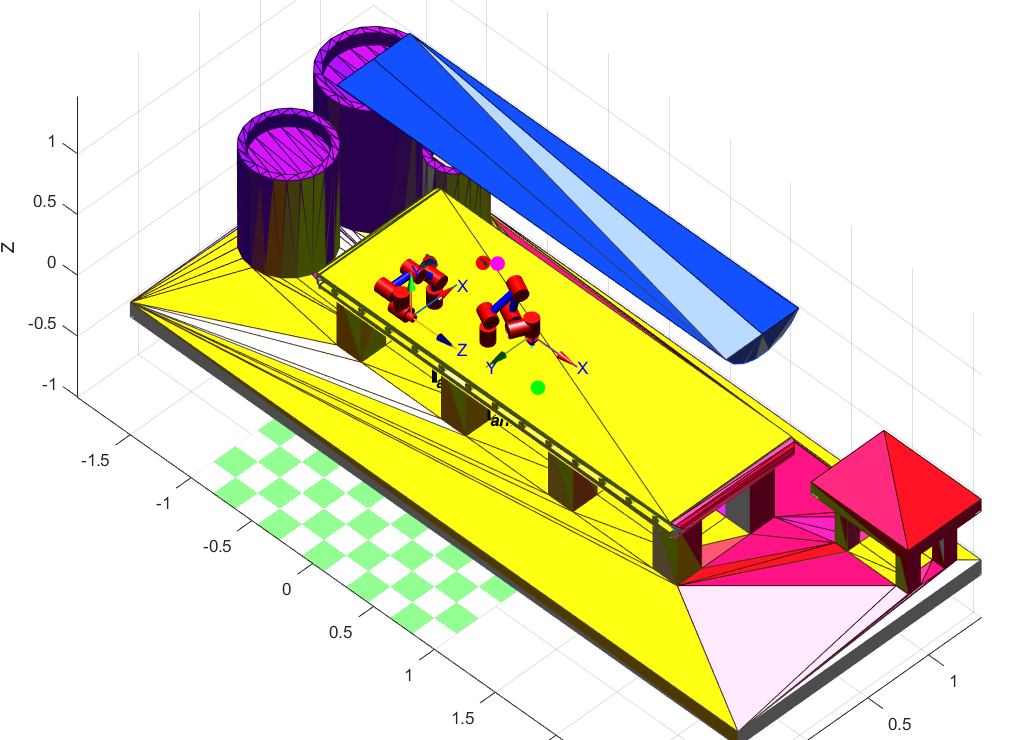

DEBUG:arm2 current position =0.40797     -0.1737     0.46741
DEBUG:arm2 current position =0.37885   -0.019391     0.78005
DEBUG:arm2 current position =0.46703     0.50815     0.64267
DEBUG:arm2 current position =0.45092     0.44615     0.24644
DEBUG:arm2 current position =0.41999     0.38006     0.19998
DEBUG: Final position ofarm2 =0.41999     0.38006     0.19998


% 1. STEP: MOVING ARM 1 TO GRASP TOP HOUSING
%% first part
qInitial = arm1CurrentQ;
qFinal   = arm1GoalQ;
t = 25; % number of timesteps - will be fine-tuned
qTrajectory = jtraj(qInitial, qFinal, t);

% NO DEBUG
% arm1.model.plot(q_trajectory);
% WITH DEBUG
arm1.PlotWithStatus(qTrajectory, 5);

% Updating
arm1CurrentPose = arm1.model.fkine(arm1.model.getpos());
arm1CurrentQ = arm1.model.getpos();

disp(strcat('Desired position for arm1 = ',num2str(transl(arm1GoalPose)')));

Desired position for arm1 =0.42        0.38         0.2


disp(strcat('ERROR (x,y,z) for arm1 = ',num2str(sqrt(sum((transl(arm1GoalPose)' - transl(arm1CurrentPose)').^2)))));

ERROR (x,y,z) for arm1 =6.1241e-05


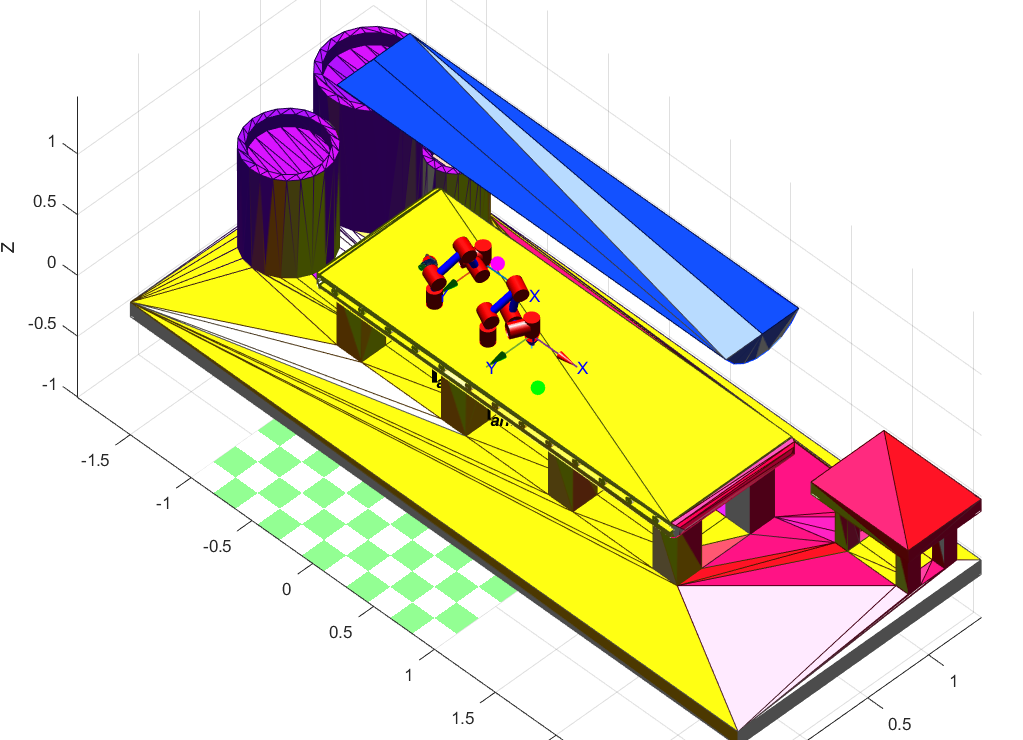

DEBUG:arm1 current position =-0.075166    -0.18746       0.409
DEBUG:arm1 current position =-0.42951    -0.15387     0.33805
DEBUG:arm1 current position =-0.6074     0.34992     0.23593
DEBUG:arm1 current position =-0.29308      0.6004     0.20085
DEBUG:arm1 current position =-0.19999         0.6     0.20003
DEBUG: Final position ofarm1 =-0.19999         0.6     0.20003


% 2. STEP: MOVING ARM 2 TO GRASP CIRCUIT BOARD
% second part
qInitial = arm2CurrentQ;
qFinal = arm2GoalQ;
t = 25; % number of timesteps - will be fine-tuned
qTrajectory = jtraj(qInitial, qFinal, t);

% NO DEBUG
% arm2.model.plot(q_trajectory);
% WITH DEBUG
arm2.PlotWithStatus(qTrajectory, 5);

% Updating
arm2CurrentQ = arm2.model.getpos();
arm2CurrentPose = arm2.model.fkine(arm2CurrentQ);

disp(strcat('Desired position for arm2 = ',num2str(transl(arm2GoalPose)')));

Desired position for arm2 =-0.2         0.6         0.2


disp(strcat('ERROR (x,y,z) for arm2 = ',num2str(sqrt(sum((transl(arm2GoalPose)' - transl(arm2CurrentPose)').^2)))));

ERROR (x,y,z) for arm2 =3.5509e-05


c) Simulate moving the arms together so as to place the circuit board into the top of the housing;

**R: Once arm1 has obj1 and arm2 has obj2, we must move both arms towars each other (circuit board on top of housing), and get to the same point in space (not colliding), in order to connect the parts.**

DEBUG: Final position ofarm2 =0.41999     0.38006     0.19998


DEBUG: Final position ofarm2 =0.42007     0.38011         0.2


DEBUG: Final position ofarm2 =0.42061     0.38049     0.20014


DEBUG: Final position ofarm2 =0.42201     0.38147      0.2005


DEBUG: Final position ofarm2 =0.42466     0.38328     0.20122


DEBUG: Final position ofarm2 =0.42891     0.38608     0.20248


DEBUG: Final position ofarm2 =0.4351     0.38993     0.20452


DEBUG: Final position ofarm2 =0.4436     0.39481     0.20769


DEBUG: Final position ofarm2 =0.45476     0.40054     0.21245


DEBUG: Final position ofarm2 =0.46891     0.40675     0.21941


DEBUG: Final position ofarm2 =0.48631     0.41287     0.22927


DEBUG: Final position ofarm2 =0.50709     0.41807     0.24284


DEBUG: Final position ofarm2 =0.53111     0.42128     0.26099


DEBUG: Final position ofarm2 =0.55789     0.42119     0.28456


DEBUG: Final position ofarm2 =0.58646     0.41635     0.31428


DEBUG: Final position ofarm2 =0.61526     0.40537     0.35062


DEBUG: Final position ofarm2 =0.64213     0.38705     0.39372


DEBUG: Final position ofarm2 =0.66434     0.36075     0.44324


DEBUG: Final position ofarm2 =0.67878     0.32661     0.49827


DEBUG: Final position ofarm2 =0.68235     0.28577      0.5573


DEBUG: Final position ofarm2 =0.67231     0.24049     0.61827


DEBUG: Final position ofarm2 =0.64682       0.194     0.67866


DEBUG: Final position ofarm2 =0.60535      0.1502     0.73568


DEBUG: Final position ofarm2 =0.54896     0.11323     0.78654


DEBUG: Final position ofarm2 =0.4803    0.086758     0.82872


DEBUG: Final position ofarm2 =0.40339    0.073518      0.8602


DEBUG: Final position ofarm2 =0.3231    0.074811     0.87971


DEBUG: Final position ofarm2 =0.2445     0.09034     0.88682


DEBUG: Final position ofarm2 =0.1722      0.1183     0.88198


DEBUG: Final position ofarm2 =0.10983     0.15574      0.8664


DEBUG: Final position ofarm2 =0.059617     0.19904     0.84189


DEBUG: Final position ofarm2 =0.022386     0.24449     0.81063


DEBUG: Final position ofarm2 =-0.0023392     0.28879     0.77496


DEBUG: Final position ofarm2 =-0.01601     0.32934     0.73712


DEBUG: Final position ofarm2 =-0.020673     0.36447     0.69908


DEBUG: Final position ofarm2 =-0.018595     0.39334     0.66247


DEBUG: Final position ofarm2 =-0.011964     0.41591     0.62848


DEBUG: Final position ofarm2 =-0.0026831     0.43267      0.5979


DEBUG: Final position ofarm2 =0.0077298     0.44445     0.57114


DEBUG: Final position ofarm2 =0.018159     0.45223     0.54833


DEBUG: Final position ofarm2 =0.027858     0.45698     0.52935


DEBUG: Final position ofarm2 =0.036377      0.4596     0.51397


DEBUG: Final position ofarm2 =0.0435     0.46082     0.50184


DEBUG: Final position ofarm2 =0.049168     0.46121      0.4926


DEBUG: Final position ofarm2 =0.053435     0.46118     0.48585


DEBUG: Final position ofarm2 =0.056427       0.461     0.48122


DEBUG: Final position ofarm2 =0.058322     0.46082     0.47833


DEBUG: Final position ofarm2 =0.059336      0.4607      0.4768


DEBUG: Final position ofarm2 =0.059725     0.46065     0.47621


DEBUG: Final position ofarm2 =0.059782     0.46064     0.47613


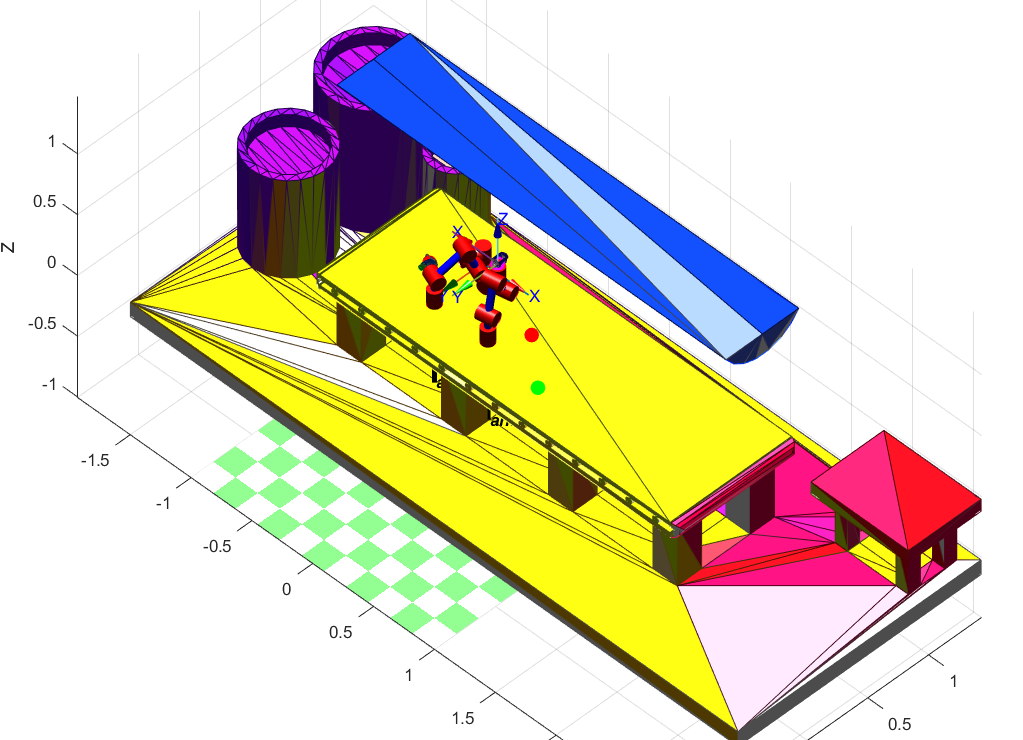

% 3. STEP: MOVING ARM 1 TO FIRST ASSEMBLY POSE
qInitial = arm1CurrentQ;
qFinal = arm1AssemblyQ;
t = 50; % number of timesteps - will be fine-tuned
qArm1Trajectory = jtraj(qInitial, qFinal, t);
%arm1.model.plot(qArm1Trajectory);

for i=1:size(qArm1Trajectory,1)
    arm1.PlotWithStatus(qArm1Trajectory(i,:), 5);
    
    tr_Obj_E = arm1.model.fkine(qArm1Trajectory(i,:))*inv(topHousingPose);
    topHousingPose = tr_Obj_E * topHousingPose* trotx(deg2rad(90))*transl(0,0.02,0);
    
    top_points = [topHousingPose * [topVerts,ones(topVertexCount,1)]']'; 
    top_h.Vertices = top_points(:,1:3);
end


%arm1.PlotWithStatus(qArm1Trajectory, 5);

arm1CurrentQ    = arm1.model.getpos();

DEBUG: Final position ofarm1 =-0.19999         0.6     0.20003


DEBUG: Final position ofarm1 =-0.19996     0.60001     0.20006


DEBUG: Final position ofarm1 =-0.19974     0.60012      0.2002


DEBUG: Final position ofarm1 =-0.19918     0.60041     0.20057


DEBUG: Final position ofarm1 =-0.19812     0.60094     0.20126


DEBUG: Final position ofarm1 =-0.19645     0.60178     0.20237


DEBUG: Final position ofarm1 =-0.19406     0.60294     0.20396


DEBUG: Final position ofarm1 =-0.19086     0.60445      0.2061


DEBUG: Final position ofarm1 =-0.18679      0.6063     0.20886


DEBUG: Final position ofarm1 =-0.18177     0.60847     0.21231


DEBUG: Final position ofarm1 =-0.17578      0.6109     0.21649


DEBUG: Final position ofarm1 =-0.16879     0.61352     0.22146


DEBUG: Final position ofarm1 =-0.16078     0.61623     0.22728


DEBUG: Final position ofarm1 =-0.15178     0.61893     0.23399


DEBUG: Final position ofarm1 =-0.14181     0.62149     0.24162


DEBUG: Final position ofarm1 =-0.13094     0.62375      0.2502


DEBUG: Final position ofarm1 =-0.11923     0.62559     0.25974


DEBUG: Final position ofarm1 =-0.10681     0.62684     0.27023


DEBUG: Final position ofarm1 =-0.093796     0.62736     0.28167


DEBUG: Final position ofarm1 =-0.080351     0.62703       0.294


DEBUG: Final position ofarm1 =-0.06665     0.62574     0.30717


DEBUG: Final position ofarm1 =-0.052882     0.62339     0.32109


DEBUG: Final position ofarm1 =-0.039249     0.61995     0.33567


DEBUG: Final position ofarm1 =-0.025951     0.61539     0.35078


DEBUG: Final position ofarm1 =-0.013185     0.60974      0.3663


DEBUG: Final position ofarm1 =-0.001132     0.60306     0.38206


DEBUG: Final position ofarm1 =0.010047     0.59543     0.39793


DEBUG: Final position ofarm1 =0.020222     0.58699     0.41374


DEBUG: Final position ofarm1 =0.029296     0.57789     0.42934


DEBUG: Final position ofarm1 =0.037207      0.5683     0.44456


DEBUG: Final position ofarm1 =0.043936      0.5584     0.45928


DEBUG: Final position ofarm1 =0.049497     0.54837     0.47337


DEBUG: Final position ofarm1 =0.053941     0.53839     0.48671


DEBUG: Final position ofarm1 =0.05735     0.52864     0.49921


DEBUG: Final position ofarm1 =0.059826     0.51926     0.51079


DEBUG: Final position ofarm1 =0.061492     0.51039     0.52141


DEBUG: Final position ofarm1 =0.06248     0.50213     0.53103


DEBUG: Final position ofarm1 =0.062926     0.49458     0.53962


DEBUG: Final position ofarm1 =0.06296     0.48778      0.5472


DEBUG: Final position ofarm1 =0.062706      0.4818     0.55377


DEBUG: Final position ofarm1 =0.062275     0.47663     0.55937


DEBUG: Final position ofarm1 =0.06176     0.47227     0.56402


DEBUG: Final position ofarm1 =0.061235     0.46871      0.5678


DEBUG: Final position ofarm1 =0.060757     0.46591     0.57075


DEBUG: Final position ofarm1 =0.06036     0.46381     0.57295


DEBUG: Final position ofarm1 =0.060062     0.46234     0.57448


DEBUG: Final position ofarm1 =0.059865     0.46141     0.57545


DEBUG: Final position ofarm1 =0.059757     0.46091     0.57597


DEBUG: Final position ofarm1 =0.059715     0.46072     0.57617


DEBUG: Final position ofarm1 =0.059709     0.46069      0.5762


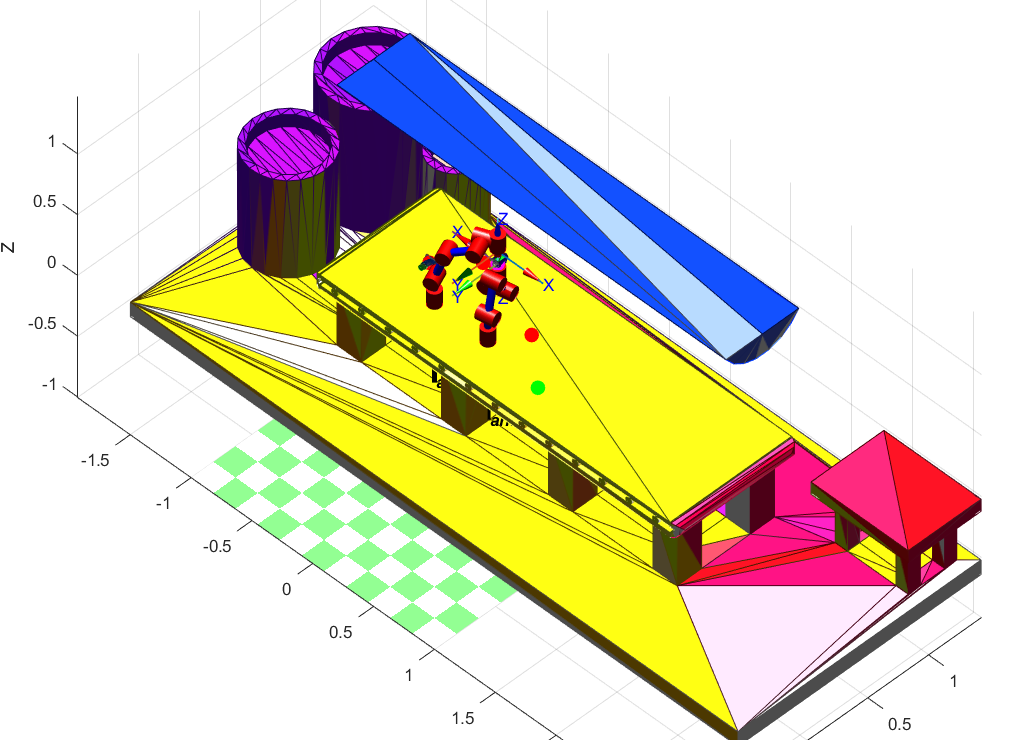

% 4. STEP: MOVING ARM 2 TO FIRST ASSEMBLY POSE
qInitial = arm2CurrentQ;
qFinal = arm2AssemblyQ;
t = 50; % number of timesteps - will be fine-tuned
qArm2Trajectory = jtraj(qInitial, qFinal, t);

for i=1:size(qArm2Trajectory,1)
    arm2.PlotWithStatus(qArm2Trajectory(i,:), 5);
    
    tr_Obj_E = arm2.model.fkine(qArm2Trajectory(i,:))*inv(circuitBoardPose);
    
    %circuitBoardPose = tr_Obj_E * circuitBoardPose* trotx(deg2rad(90))*transl(0,0.02,0);%*trotx(deg2rad(90));
    circuitBoardPose = tr_Obj_E * circuitBoardPose* trotx(deg2rad(90))*transl(0,0.02,0)*troty(-pi/2)*transl(0.0200,0,-0.025)*transl(0,0.05,0.025);
    
    circ_points = [circuitBoardPose * [circVerts,ones(circVertexCount,1)]']'; 
    circ_h.Vertices = circ_points(:,1:3);
end


%arm2.PlotWithStatus(qArm2Trajectory, 5);

arm2CurrentQ = arm2.model.getpos();

% used as test to get the right pose - DONT UNCOMMENT IT
%circuitBoardPose = circuitBoardPose*troty(-pi/2)*transl(0.0200,0,-0.025)

%circuitBoardPose = circuitBoardPose*transl(0,0.05,0.025)
%circ_points = [circuitBoardPose * [circVerts,ones(circVertexCount,1)]']';
%circ_h.Vertices = circ_points(:,1:3);

% used as test to get the right pose - DONT UNCOMMENT IT
%botHousingPose = botHousingPose*trotx(pi)*troty(-pi/2)*transl(-0.01,-0.025,0)
%bot_points = [botHousingPose * [botVerts,ones(botVertexCount,1)]']';
%bot_h.Vertices = bot_points(:,1:3)

d) Determine a pose to grasp the bottom of the shell with the hand that was holding the circuit board;

**R: Given another point, get there by interpolation**

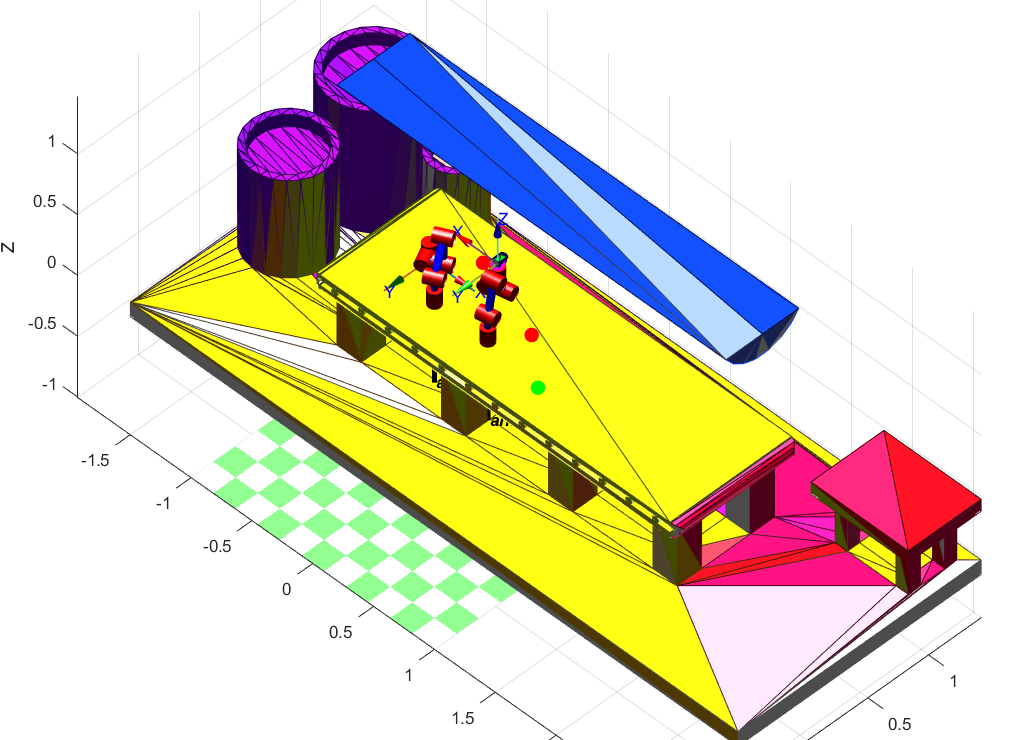

DEBUG:arm1 current position =0.059098     0.46343     0.57414
DEBUG:arm1 current position =0.052033      0.4869       0.556
DEBUG:arm1 current position =0.022474     0.53952     0.51048
DEBUG:arm1 current position =-0.053977     0.60087     0.43742
DEBUG:arm1 current position =-0.17815     0.62401     0.35213
DEBUG:arm1 current position =-0.30486     0.58053      0.2797
DEBUG:arm1 current position =-0.38649      0.4988     0.23606
DEBUG:arm1 current position =-0.42004     0.42872     0.21799
DEBUG:arm1 current position =-0.42888      0.3941     0.21306
DEBUG:arm1 current position =-0.42997     0.38805     0.21244
DEBUG: Final position ofarm1 =-0.42997     0.38805     0.21244


% 5. STEP: MOVING ARM 2 TO GRASP BOT HOUSING
qInitial = arm2CurrentQ;
%qFinal = wrapToPi(arm2.model.ikine(botHousingPose, elbowUp));
qFinal = wrapToPi(arm2.model.ikcon(botHousingPose, arm2_elbowDown));
t = 50; % number of timesteps - will be fine-tuned
qArm2Trajectory = jtraj(qInitial, qFinal, t);
%arm2.model.plot(qArm2Trajectory);
arm2.PlotWithStatus(qArm2Trajectory,5);


arm2CurrentQ    = arm2.model.getpos();

e) Simulate bringing the parts together, without colliding so as to complete the assembly;

**R: Bring the third object back**

DEBUG: Final position ofarm1 =-0.42997     0.38805     0.21244


DEBUG: Final position ofarm1 =-0.42996     0.38811     0.21245


DEBUG: Final position ofarm1 =-0.4299     0.38848     0.21249


DEBUG: Final position ofarm1 =-0.42973     0.38944     0.21258


DEBUG: Final position ofarm1 =-0.42941     0.39125     0.21276


DEBUG: Final position ofarm1 =-0.42888      0.3941     0.21306


DEBUG: Final position ofarm1 =-0.42808     0.39816     0.21352


DEBUG: Final position ofarm1 =-0.42692     0.40357     0.21418


DEBUG: Final position ofarm1 =-0.42528     0.41043     0.21509


DEBUG: Final position ofarm1 =-0.42305      0.4188     0.21634


DEBUG: Final position ofarm1 =-0.42004     0.42872     0.21799


DEBUG: Final position ofarm1 =-0.41609     0.44015     0.22016


DEBUG: Final position ofarm1 =-0.41098     0.45303     0.22293


DEBUG: Final position ofarm1 =-0.4045     0.46723     0.22643


DEBUG: Final position ofarm1 =-0.3964     0.48257     0.23077


DEBUG: Final position ofarm1 =-0.38649      0.4988     0.23606


DEBUG: Final position ofarm1 =-0.37457     0.51561      0.2424


DEBUG: Final position ofarm1 =-0.36049     0.53262     0.24988


DEBUG: Final position ofarm1 =-0.34417     0.54941     0.25857


DEBUG: Final position ofarm1 =-0.3256     0.56554     0.26851


DEBUG: Final position ofarm1 =-0.30486     0.58053      0.2797


DEBUG: Final position ofarm1 =-0.28213     0.59391     0.29211


DEBUG: Final position ofarm1 =-0.25769     0.60527     0.30568


DEBUG: Final position ofarm1 =-0.23191     0.61424     0.32031


DEBUG: Final position ofarm1 =-0.20523     0.62055     0.33585


DEBUG: Final position ofarm1 =-0.17815     0.62401     0.35213


DEBUG: Final position ofarm1 =-0.15117     0.62458     0.36897


DEBUG: Final position ofarm1 =-0.12482     0.62232     0.38613


DEBUG: Final position ofarm1 =-0.099573     0.61741     0.40341


DEBUG: Final position ofarm1 =-0.075847     0.61014     0.42058


DEBUG: Final position ofarm1 =-0.053977     0.60087     0.43742


DEBUG: Final position ofarm1 =-0.034206     0.59001     0.45374


DEBUG: Final position ofarm1 =-0.016673     0.57801     0.46934


DEBUG: Final position ofarm1 =-0.0014231     0.56532     0.48408


DEBUG: Final position ofarm1 =0.011587     0.55236     0.49782


DEBUG: Final position ofarm1 =0.022474     0.53952     0.51048


DEBUG: Final position ofarm1 =0.03141     0.52714     0.52198


DEBUG: Final position ofarm1 =0.038605     0.51551     0.53229


DEBUG: Final position ofarm1 =0.044287     0.50483     0.54138


DEBUG: Final position ofarm1 =0.048689     0.49526     0.54928


DEBUG: Final position ofarm1 =0.052033      0.4869       0.556


DEBUG: Final position ofarm1 =0.054524      0.4798     0.56159


DEBUG: Final position ofarm1 =0.05634     0.47396     0.56612


DEBUG: Final position ofarm1 =0.05763     0.46935     0.56966


DEBUG: Final position ofarm1 =0.058517     0.46587      0.5723


DEBUG: Final position ofarm1 =0.059098     0.46343     0.57414


DEBUG: Final position ofarm1 =0.059448     0.46189      0.5753


DEBUG: Final position ofarm1 =0.05963     0.46106     0.57592


DEBUG: Final position ofarm1 =0.059699     0.46074     0.57616


DEBUG: Final position ofarm1 =0.059709     0.46069      0.5762


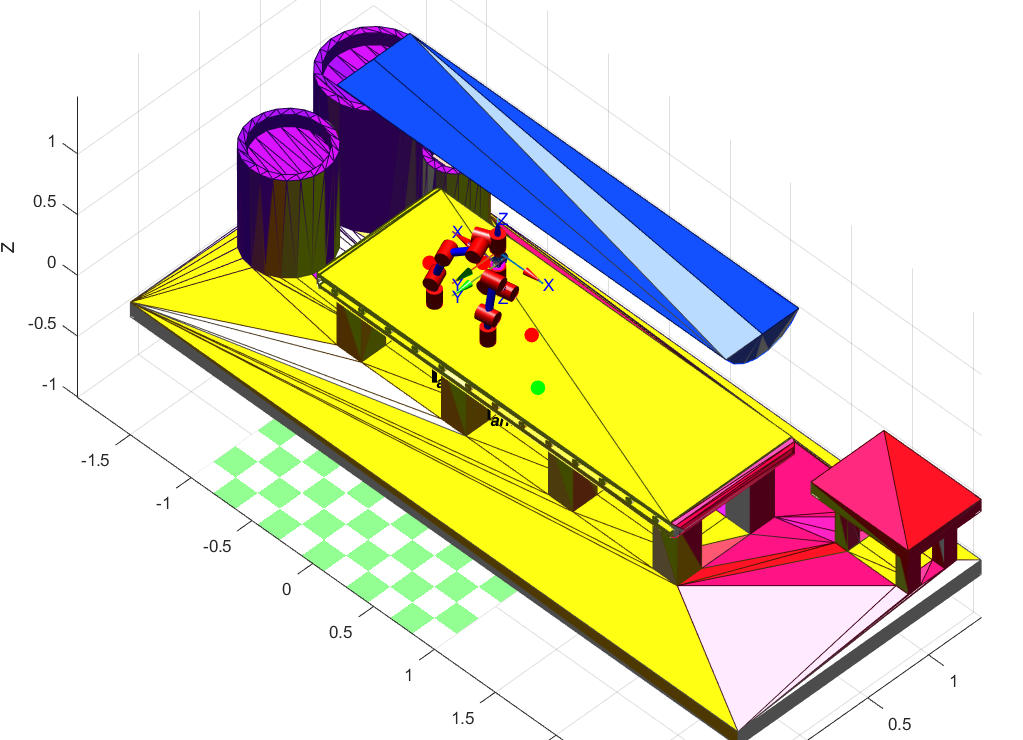

% 6. STEP: MOVING ARM 2 TO THE SAME POSITION AS ARM 1

arm2GoalPose = arm2AssemblyPose;
arm2GoalQ = arm2AssemblyQ;

qInitial = arm2CurrentQ;
qFinal = arm2GoalQ;
t = 50; % number of timesteps - will be fine-tuned
qArm2Trajectory = jtraj(qInitial, qFinal, t);

for i=1:size(qArm2Trajectory,1)
    arm2.PlotWithStatus(qArm2Trajectory(i,:), 5);
    
    tr_Obj_E = arm2.model.fkine(qArm2Trajectory(i,:))*inv(botHousingPose);
    
    %botHousingPose = tr_Obj_E * botHousingPose* trotx(deg2rad(90))*transl(0,0.02,0);
    botHousingPose = tr_Obj_E * botHousingPose* trotx(deg2rad(90))*transl(0,0.02,0)*trotx(pi)*troty(-pi/2)*transl(-0.01,-0.025,0);
    
    bot_points = [botHousingPose * [botVerts,ones(botVertexCount,1)]']'; 
    bot_h.Vertices = bot_points(:,1:3);
end


%arm2.PlotWithStatus(qArm2Trajectory,5);

arm2CurrentQ    = arm2.model.getpos();

f) Determine a pose, and simulated path so as to drop the completely assembled part off into another box in front of the two robots.

**R: Probably make Z pointing down.**

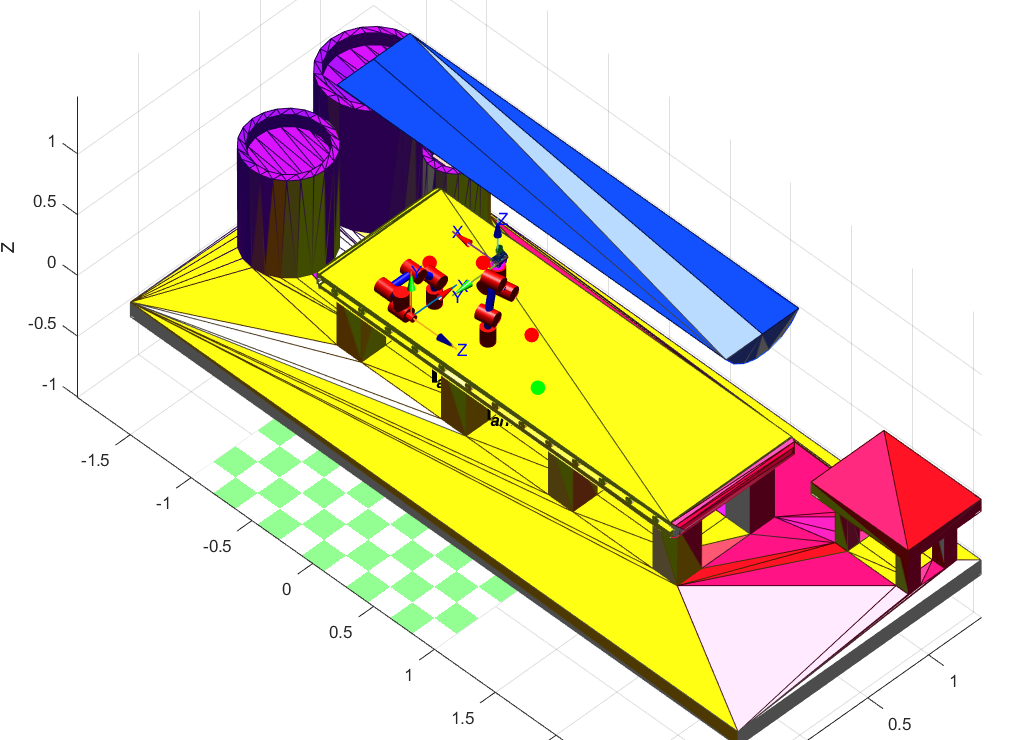

DEBUG:arm1 current position =0.054524     0.46703     0.57497
DEBUG:arm1 current position =0.0039772      0.5166     0.56469
DEBUG:arm1 current position =-0.14866     0.58947     0.54258
DEBUG:arm1 current position =-0.40646     0.55397     0.51486
DEBUG:arm1 current position =-0.60215     0.30656     0.48923
DEBUG:arm1 current position =-0.55181   -0.012335     0.46695
DEBUG:arm1 current position =-0.32896    -0.18393     0.44622
DEBUG:arm1 current position =-0.13196    -0.19812     0.42935
DEBUG:arm1 current position =-0.040943    -0.17214     0.42045
DEBUG:arm1 current position =-0.02575    -0.16554     0.41884
DEBUG: Final position ofarm1 =-0.02575    -0.16554     0.41884


% 7. STEP: MAKING ARM 2 LEAVE THE ASSEMBLY POINT (return to initial pose)
% Manualy set

qInitial = arm2CurrentQ;
qFinal = q0; % initial pose
t = 50; % number of timesteps - will be fine-tuned
qArm2Trajectory = jtraj(qInitial, qFinal, t);

arm2.PlotWithStatus(qArm2Trajectory, 5);


arm2CurrentQ    = arm2.model.getpos();

DEBUG: Final position ofarm2 =0.059782     0.46064     0.47613


DEBUG: Final position ofarm2 =0.059754     0.46063      0.4762


DEBUG: Final position ofarm2 =0.059559     0.46053     0.47672


DEBUG: Final position ofarm2 =0.059055     0.46028     0.47808


DEBUG: Final position ofarm2 =0.058118     0.45978     0.48063


DEBUG: Final position ofarm2 =0.056654     0.45894     0.48466


DEBUG: Final position ofarm2 =0.054598     0.45761     0.49047


DEBUG: Final position ofarm2 =0.051922     0.45561     0.49828


DEBUG: Final position ofarm2 =0.048644     0.45267     0.50832


DEBUG: Final position ofarm2 =0.044841     0.44848     0.52075


DEBUG: Final position ofarm2 =0.040667     0.44264     0.53572


DEBUG: Final position ofarm2 =0.036367     0.43469     0.55326


DEBUG: Final position ofarm2 =0.032301     0.42412     0.57337


DEBUG: Final position ofarm2 =0.02896     0.41039     0.59588


DEBUG: Final position ofarm2 =0.026976       0.393     0.62051


DEBUG: Final position ofarm2 =0.027118     0.37153     0.64678


DEBUG: Final position ofarm2 =0.030275      0.3457     0.67406


DEBUG: Final position ofarm2 =0.037409     0.31547     0.70149


DEBUG: Final position ofarm2 =0.049492     0.28108     0.72805


DEBUG: Final position ofarm2 =0.06741     0.24309      0.7526


DEBUG: Final position ofarm2 =0.09186     0.20243     0.77388


DEBUG: Final position ofarm2 =0.12324     0.16033     0.79066


DEBUG: Final position ofarm2 =0.16156      0.1183     0.80176


DEBUG: Final position ofarm2 =0.20637    0.077964     0.80621


DEBUG: Final position ofarm2 =0.25674    0.040976     0.80328


DEBUG: Final position ofarm2 =0.31131   0.0088268     0.79259


DEBUG: Final position ofarm2 =0.36836   -0.017284     0.77414


DEBUG: Final position ofarm2 =0.42599   -0.036561     0.74831


DEBUG: Final position ofarm2 =0.48224   -0.048676     0.71585


DEBUG: Final position ofarm2 =0.53527    -0.05378     0.67781


DEBUG: Final position ofarm2 =0.58354    -0.05245     0.63547


DEBUG: Final position ofarm2 =0.62589   -0.045605     0.59024


DEBUG: Final position ofarm2 =0.66161   -0.034383     0.54354


DEBUG: Final position ofarm2 =0.69045   -0.020018     0.49675


DEBUG: Final position ofarm2 =0.7126  -0.0037278     0.45109


DEBUG: Final position ofarm2 =0.72857    0.013386     0.40761


DEBUG: Final position ofarm2 =0.73913    0.030393     0.36713


DEBUG: Final position ofarm2 =0.74521    0.046569     0.33025


DEBUG: Final position ofarm2 =0.74779    0.061397     0.29735


DEBUG: Final position ofarm2 =0.74783    0.074554     0.26863


DEBUG: Final position ofarm2 =0.74619    0.085875     0.24411


DEBUG: Final position ofarm2 =0.74363    0.095325     0.22371


DEBUG: Final position ofarm2 =0.74074     0.10296     0.20721


DEBUG: Final position ofarm2 =0.73796      0.1089     0.19434


DEBUG: Final position ofarm2 =0.73559      0.1133     0.18477


DEBUG: Final position ofarm2 =0.73378     0.11636     0.17811


DEBUG: Final position ofarm2 =0.73258     0.11828      0.1739


DEBUG: Final position ofarm2 =0.73191      0.1193     0.17166


DEBUG: Final position ofarm2 =0.73165      0.1197      0.1708


DEBUG: Final position ofarm2 =0.73161     0.11975     0.17067


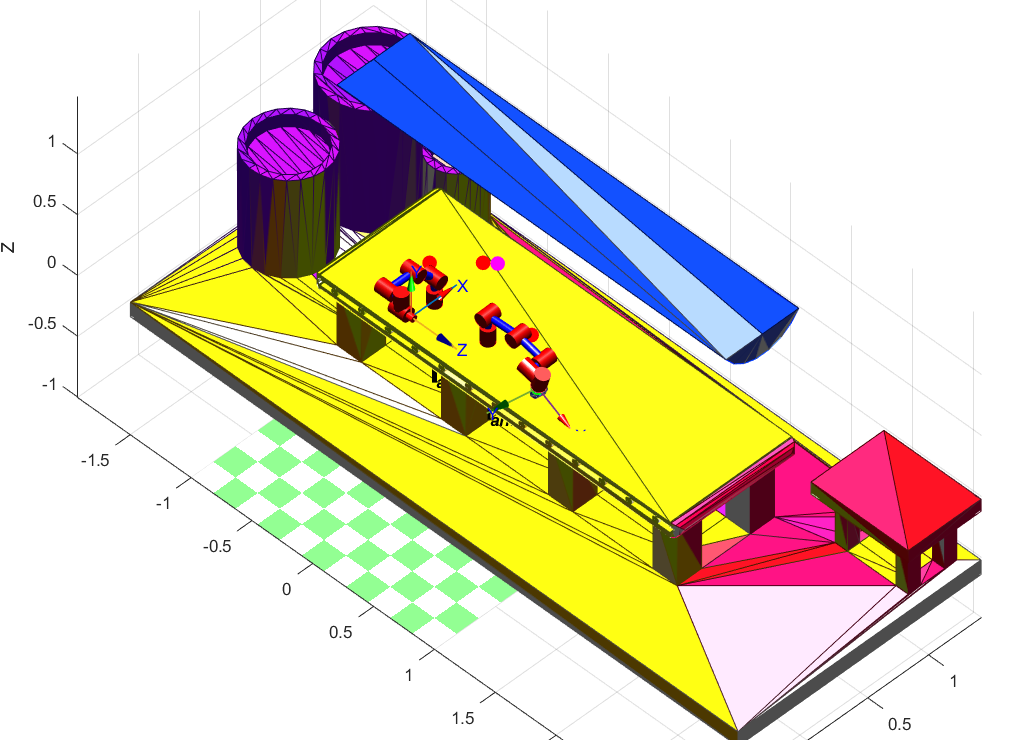

% 8. STEP: MAKING ARM 1 DROP THE FINAL PART
% Manualy set

initialGuess = [0.0236   -2.2619   -0.2846   -1.5516    1.5708   -1.4059];
qInitial = arm1CurrentQ;
qFinal = arm1.model.ikcon(releasePose,initialGuess);
t = 50; % number of timesteps - will be fine-tuned
qArm1Trajectory = jtraj(qInitial, qFinal, t);

for i=1:size(qArm1Trajectory,1)
    arm1.PlotWithStatus(qArm1Trajectory(i,:), 5);
    
    tr_top_E  = arm1.model.fkine(qArm1Trajectory(i,:))*inv(topHousingPose);
    tr_circ_E = arm1.model.fkine(qArm1Trajectory(i,:))*inv(circuitBoardPose);
    tr_bot_E  = arm1.model.fkine(qArm1Trajectory(i,:))*inv(botHousingPose);
    
    topHousingPose   = tr_top_E * topHousingPose * trotx(deg2rad(90))*transl(0,0.02,0) ;
    circuitBoardPose = tr_circ_E * circuitBoardPose* trotx(deg2rad(90))*transl(0,0.02,0)*troty(-pi/2)*transl(0.0200,0,-0.025)*transl(0,0.05,0.025);
    botHousingPose   = tr_bot_E * botHousingPose* trotx(deg2rad(90))*transl(0,0.02,0)*trotx(pi)*troty(-pi/2)*transl(-0.01,-0.025,0);;
    
    
    top_points      = [topHousingPose * [topVerts,ones(topVertexCount,1)]']'; 
    top_h.Vertices  = top_points(:,1:3);
    circ_points     = [circuitBoardPose * [circVerts,ones(circVertexCount,1)]']'; 
    circ_h.Vertices = circ_points(:,1:3);
    bot_points      = [botHousingPose * [botVerts,ones(botVertexCount,1)]']'; 
    bot_h.Vertices  = bot_points(:,1:3);
end


%arm1.PlotWithStatus(qArm1Trajectory, 5);

arm1CurrentQ    = arm1.model.getpos();

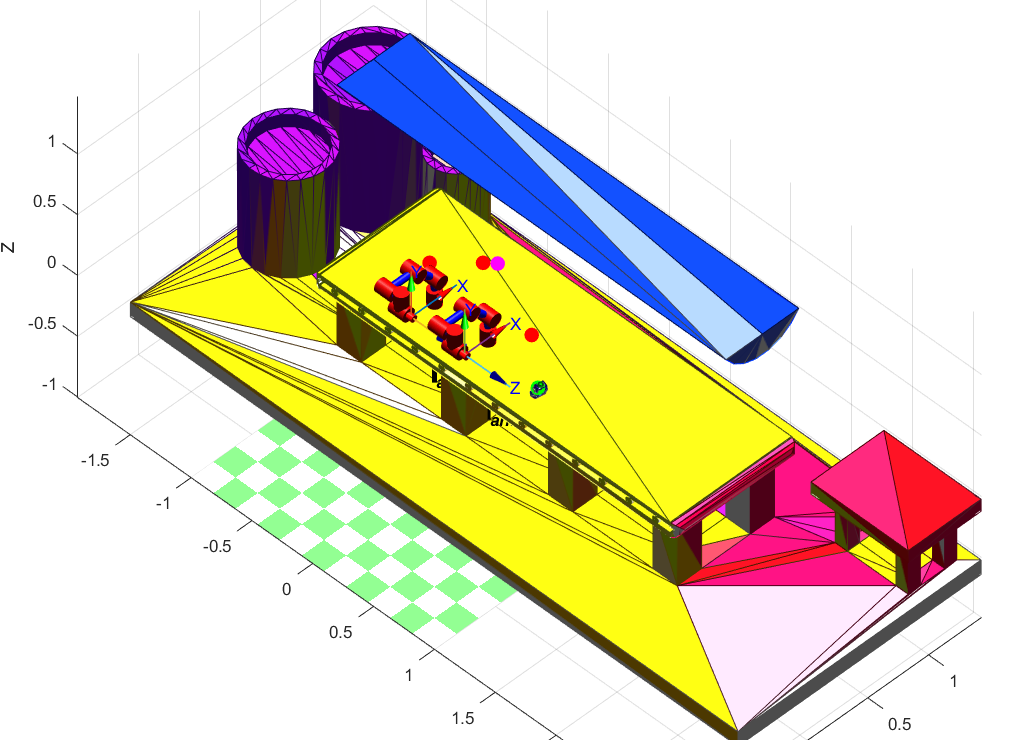

DEBUG:arm2 current position =0.73571     0.12304     0.17827
DEBUG:arm2 current position =0.76486     0.15316      0.2468
DEBUG:arm2 current position =0.7851     0.22792     0.42392
DEBUG:arm2 current position =0.68238     0.29381     0.68512
DEBUG:arm2 current position =0.4469     0.20482     0.86526
DEBUG:arm2 current position =0.29505   -0.020386     0.81649
DEBUG:arm2 current position =0.31375    -0.16498     0.63634
DEBUG:arm2 current position =0.37644    -0.18402     0.49237
DEBUG:arm2 current position =0.4088    -0.16942     0.42924
DEBUG:arm2 current position =0.41425    -0.16554     0.41884
DEBUG: Final position ofarm2 =0.41425    -0.16554     0.41884


% 9. STEP: MAKING ARM 1 GO BACK TO HOME POSITION
% Manualy set

qInitial = arm1CurrentQ;
qFinal = q0; % home pose
t = 50; % number of timesteps - will be fine-tuned
qArm1Trajectory = jtraj(qInitial, qFinal, t);

arm1.PlotWithStatus(qArm1Trajectory, 5);